clc
clear 
close

run('BASIC.m')

sys_discret =
 
  0.017631 (z-0.3611) (z-0.6719)
  -------------------------------
  (z-1.365) (z-0.2212) (z-0.1986)
 
Sample time: 0.28285 seconds
Discrete-time zero/pole/gain model.



B =     0.0176   -0.0182    0.0043


A =     1.0000   -1.7848    0.6171   -0.0600



Titlework='Q12'

Titlework = 'Q12'

## Desigered System

%A_m=poly([0.1 0.2 0.02]);
A_m=poly([0.40 0.45 0.49]);


betaa=sum(A_m);
B_m=betaa*[1,zeros(1,(numel(A)-numel(B))+1)];
B_plus =B/B(1);
B_minus=  B(1);

Deg_A_o=numel(A)-numel(B_plus)-1;
A_o=[1 zeros(1,Deg_A_o)];
A_c_prim=conv(A_m,A_o);
A_c=conv(A_c_prim,B_plus);

## warning UND error

run('Warnings.m')

## MDPP with zero canselation

% [R_prim,S] = Diophantine(A,B_minus,A_c_prim)
% T=B_m_prim;
% R=B_plus;
[R,S] = Diophantine(A,B,A_c)

R =     1.0000
   -1.0330
    0.2426


S =    25.2314
   -1.1664
   -1.6003


T=betaa*[1,zeros(1,(numel(A)-numel(B))+1)]/B(1);

tfinal=100;
t = 0:T_s:tfinal;
uc=(gensig('square' , tfinal/3 , tfinal ,T_s));

u=zeros(numel(t),1);
y=zeros(numel(t),1);

var1=conv(B,T);     narv1=numel(var1);
var2=A_c(2:end);    narv2=numel(A_c(2:end));
var3=conv(A,T);     narv3=numel(var3);
for i=10:numel(t)
    y(i)=var1*uc(i:-1:i-narv1+1)-var2*y(i-1:-1:i-narv2);
    u(i)=var3*uc(i:-1:i-narv3+1)-var2*u(i-1:-1:i-narv2);
end

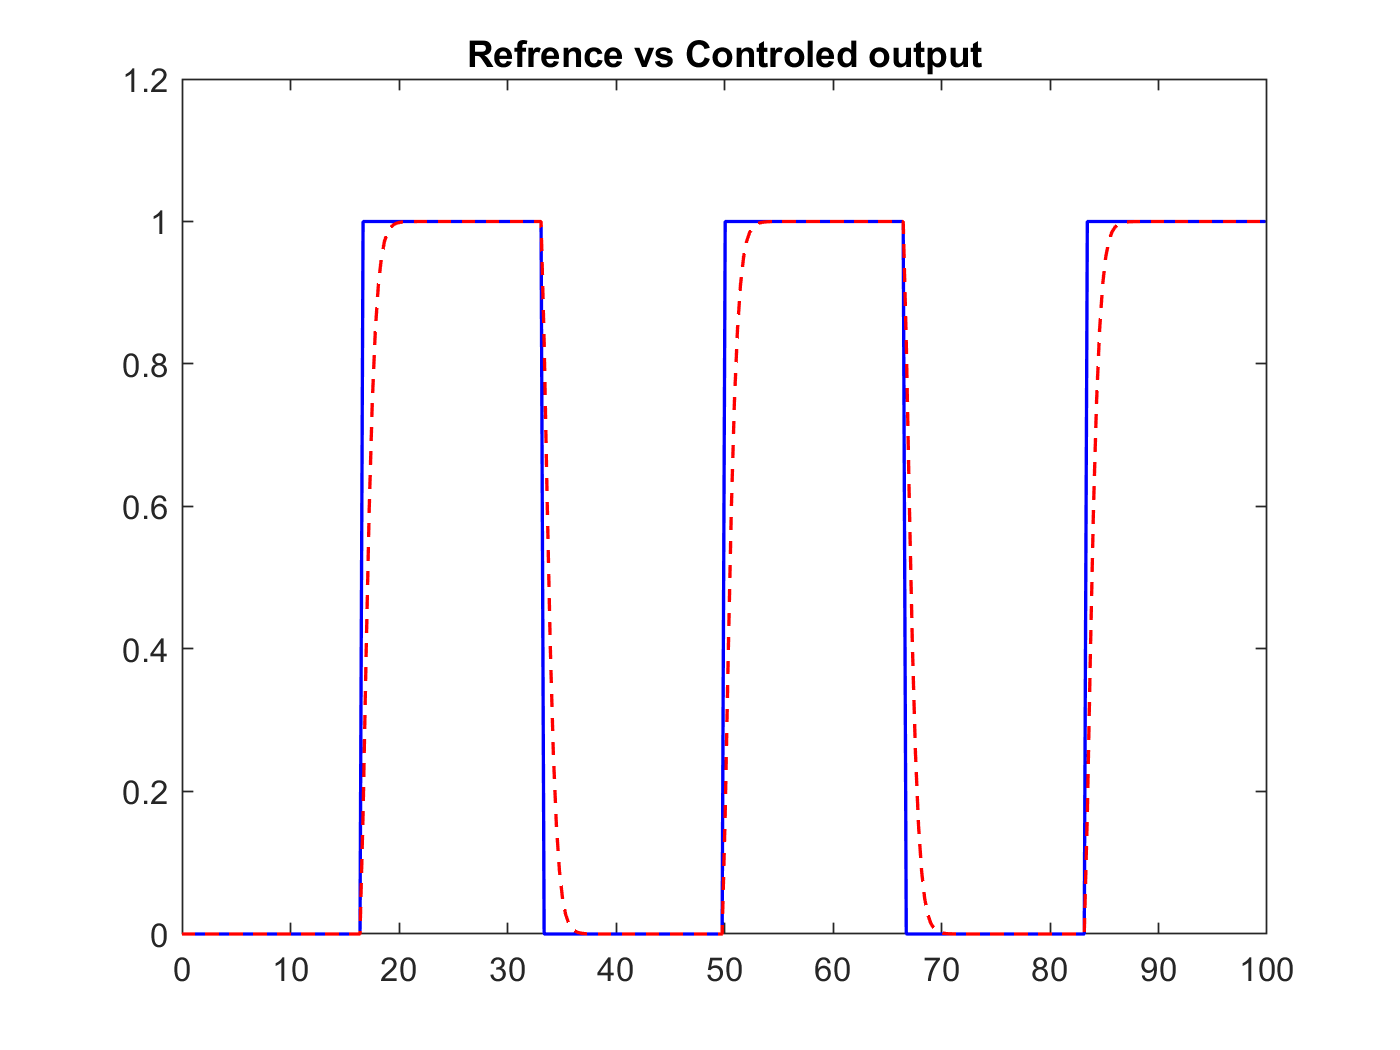

plot(t,uc,'b',t,y,'r--','LineWidth',1)
title('Refrence vs Controled output')
print(gcf,[Titlework ' Refrence vs Controled output.png'],'-dpng','-r400');

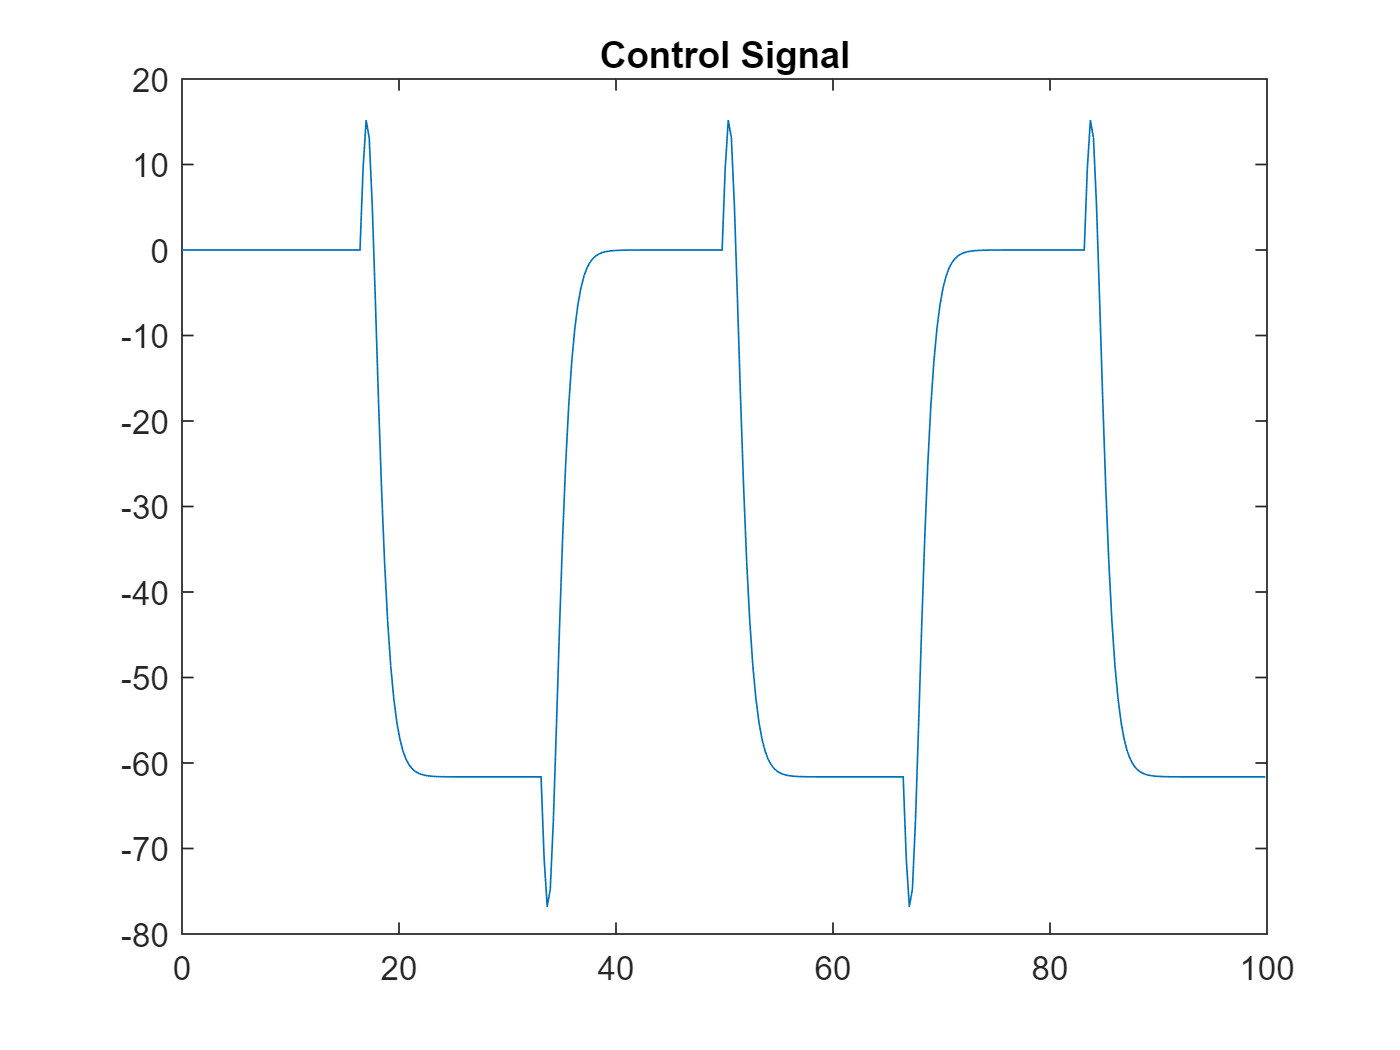


plot(t,u)
title('Control Signal')
print(gcf,[Titlework ' Control Signal.png'],'-dpng','-r400');